# Обработка звуковых сигналов

Никита Красницкий

Чтение и воспроизведение аудиофайла для представления его в матлабе.

clear all
close all
[x, fs] = audioread('Sound2.m4a');

Error using audioread (line 74)
The filename specified was not found in the MATLAB path.


%sound(x, fs);
plot(x(:,1))
plot(x(:,2))

Делаю 100 делений звукового ряда по 2652 отчета. ПОсле чего возьму 100 fft и получу временную зависимость АЧХ

A = x(1:length(x));
N = length(x)/100;
xdiv = reshape(A, [N, 100]); 

Такая строчка кода проиграет 20мой столбик (из 100) и нарисует его график

plot(xdiv(1:end,20));
%sound(2000*xdiv(1:end,20), 130*30);

100 Спектра

Xdiv = ifft(xdiv);
Xdivshift = fftshift(Xdiv);

F = linspace(-fs/2, fs/2, length(Xdivshift));
area(F, abs(Xdivshift(1:end, 1)))
xlim([0 2e3]);
ylim([0 0.02]);
title('1');

area(F, abs(Xdivshift(1:end, 2)))
xlim([0 2e3]);
ylim([0 0.02]);
title('2');

area(F, abs(Xdivshift(1:end, 3)))
xlim([0 2e3]);
ylim([0 0.02]);
title('3');

area(F, abs(Xdivshift(1:end, 4)))
xlim([0 2e3]);
ylim([0 0.02]);
title('4');

area(F, abs(Xdivshift(1:end, 8)))
xlim([0 2e3]);
ylim([0 0.02]);
title('8');

area(F, abs(Xdivshift(1:end, 16)))
xlim([0 2e3]);
ylim([0 0.02]);
title('16');

area(F, abs(Xdivshift(1:end, 70)))
xlim([0 2e3]);
ylim([0 0.02]);
title('70');

Находим "уровень" частоты 150 +/-10 (1335 - average sample)

BaseLevel(100) = 0;
for index = 1:100
    for n = 1300:1370
        BaseLevel(index) = BaseLevel(index) + Xdivshift(n,index);
    end
end
%plot(abs(BaseLevel));

???

for i = 1:50
    a = BaseLevel(i);
    BaseLevel(i) = BaseLevel(i+50);
    BaseLevel(i+50) = a;
end
plot(abs(BaseLevel));
title('Амплитуда первой гармоники со временем')

Нахождение и представление спектра 

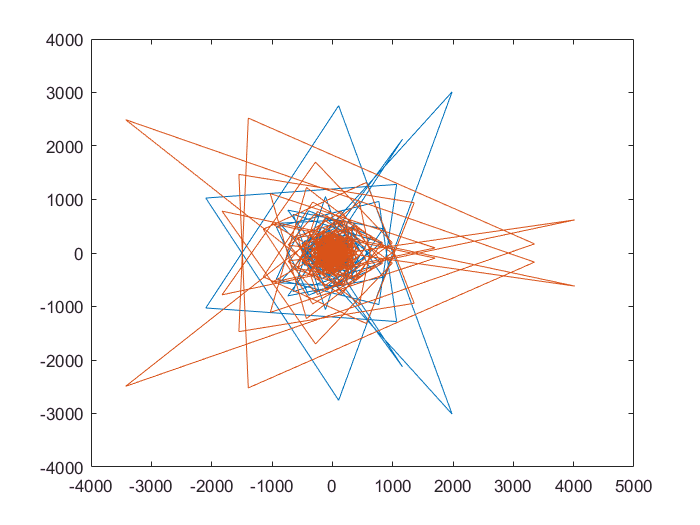

X = fft(x);

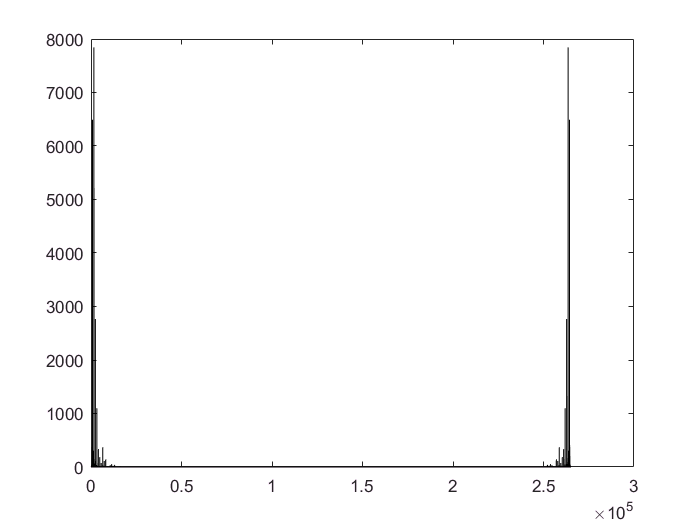

area(abs(X)) % Пример непривычного вида

представление спектра в привычном виде

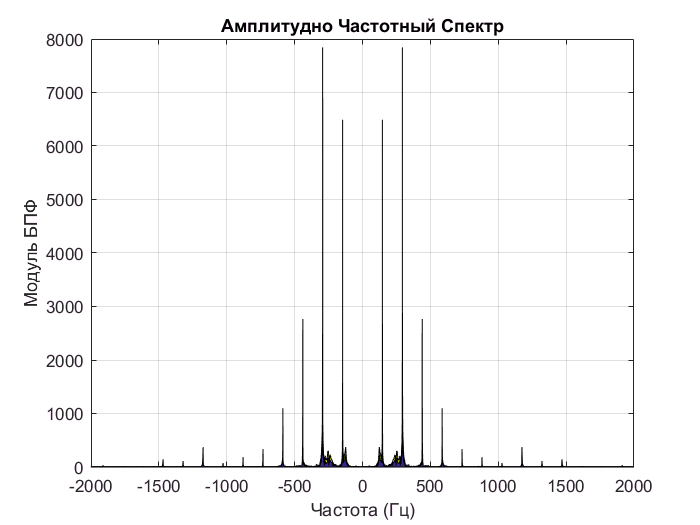

Xshift = fftshift(X);
F = linspace(-fs/2, fs/2, length(X)); % создает строку с числом єлементов равным числу элементов Х
                                      % начальное значение и кончено равны -fs/2 и fs/2
area(F, abs(Xshift))
xlim([-2e3 2e3])  % Ограничение до 2кГц - выше крыши для обертонов (гармоник)
grid on
title('Амплитудно Частотный Спектр')
ylabel('Модуль БПФ')
xlabel('Частота (Гц)')

Спектр в положительной области частот

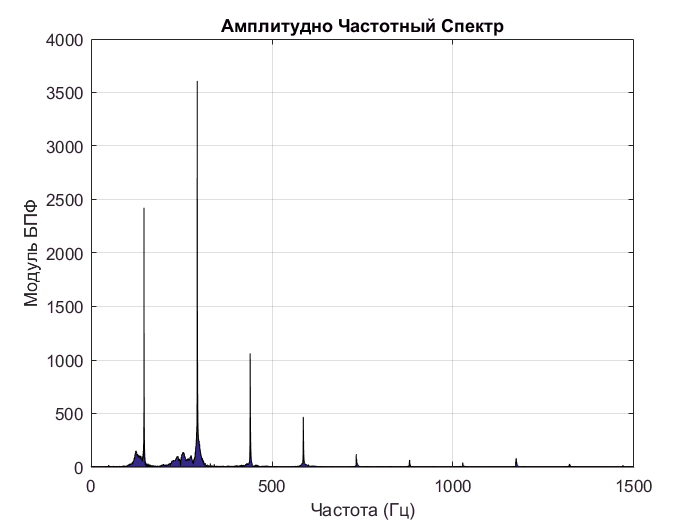

Xpos = X([1:length(X)/2]);
Fpos = linspace(0, fs/2, length(Xpos));
area(Fpos, abs(Xpos))
xlim([0 1.5e3])  % Ограничение до 1.5к
grid on
hold on
title('Амплитудно Частотный Спектр')
ylabel('Модуль БПФ')
xlabel('Частота (Гц)')

Определим частоты каждой гармоники для продолжения анализа

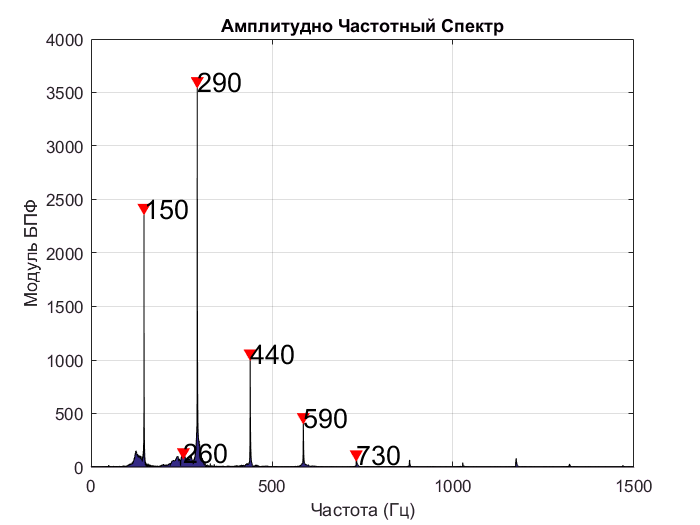

[~, locs] = findpeaks(abs(Xpos), 'MinPeakHeight', 100, 'MinPeakDistance', 150);
Fpeaks = Fpos(locs);
plot(Fpeaks, abs(Xpos(locs)),'rv', 'MarkerFaceColor', 'r');
cellpeaks = cellstr(num2str(round(Fpeaks', -1)));
text(Fpeaks, abs(Xpos(locs)), cellpeaks, 'FontSize', 16);
hold off

Для анализа обертонов можно посмотреть какие ноты попутно звучат при извлечении основного звука.

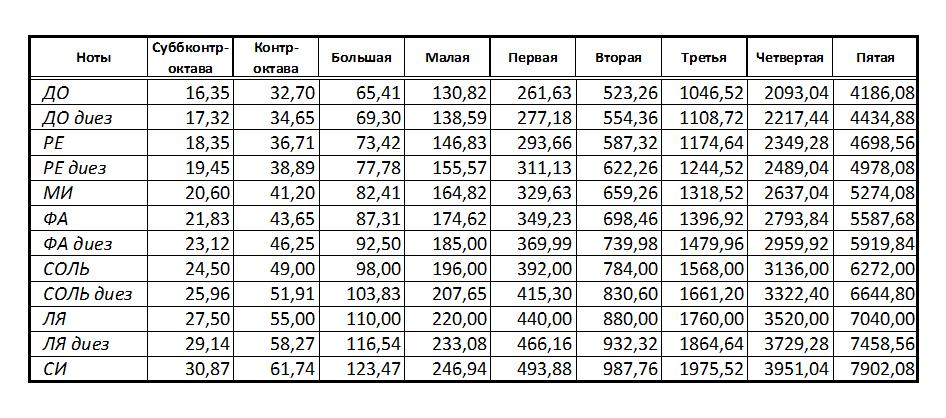

Изменение 2

X = fft(x);
plot(abs(X))
xlim([0 15.5e3])

Z = 1e-6*F.^2; % Синк на уровне первой гармоники 
Z(2,:) = Z(1,:);
Z = Z.';

plot(F, Z)
hold on
plot(F, abs(X))
hold off
title('2 Графики спектра звукового сигнала и нашей функции')


plot(F, Z)
hold on
plot(F, abs(X))
hold off
xlim([-fs/2 -fs/2+5.5e3])
ylim([0 6e3])
title('2 Наша функция в пределах первых гармоник')

X = X.*Z / 2000;
plot(F, abs(X))
xlim([-fs/2 -fs/2+5.5e3])
ylim([0 6e3])
title('2 Измененный спектр')

Изменяем амплитуды спектра звукового сигнала.

X = fft(x);
plot(abs(X))
xlim([0 15.5e3])

Z = 1e6*sinc((F) * 5.5e-3); % Синк на уровне первой гармоники 
Z(2,:) = Z(1,:);
Z = Z.';
plot(F, Z)
hold on
plot(F, abs(X))
hold off
title('Графики спектра звукового сигнала и нашей функции')


plot(F, Z)
hold on
plot(F, abs(X))
hold off
xlim([-fs/2 -fs/2+5.5e3])
ylim([0 6e3])
title('Наша функция в пределах первых гармоник')

X = X.*Z / 2000;
plot(F, abs(X))
xlim([-fs/2 -fs/2+5.5e3])
ylim([0 6e3])
title('Измененный спектр')
%X( X > length(X)/2) = X.*Z2;
%X(X<200) = 0;   
%area(F, abs(X))

Обратное Преобразование Фурье. Возвращаем звук.

y = ifft(X);
y = real(y)
sound(y, fs)
plot(y)